# FNN CNN LSTM  - use trained model

### Data Preprocessing

Get ready for the training. The inputs of the proposed models in [2] are the extracted features, which are obtained by the uniform sampling of the raw battery data. Specifically, they configure the input matrix as 30-dimensional vectors by concatenating the V, I, T charging profiles, each with 10 samples. The number of samples is chosen to consider the distinct changes in time and the model complexity. In addition, we average the data over sampling interval to prevent oscillation in short time interval.

load B0005.mat
load B0006.mat
load B0007.mat

cap5 = extract_discharge(B0005);
cap6 = extract_discharge(B0006);
cap7 = extract_discharge(B0007);

charInput5 = extract_charge_preprocessing(B0005);
charInput6 = extract_charge_preprocessing(B0006);
charInput7 = extract_charge_preprocessing(B0007);

Initial capacity for each battery data is provided as belows in the dataset:

InitC5 = 1.86; % capacity of dischage cycle 1
InitC6 = 2.04;
InitC7 = 1.89;

For better training since it retains the original distribution of data except for a scaling factor and transforms all the data into the range of [0,1]:

[xB5, yB5, ym5, yr5] = minmax_norm(charInput5, InitC5, cap5);
[xB6, yB6, ym6, yr6] = minmax_norm(charInput6, InitC6, cap6);
[xB7, yB7, ym7, yr7] = minmax_norm(charInput7, InitC7, cap7);

## Load trained model 

% https://kr.mathworks.com/matlabcentral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

load  netFNN10_B5_v1 
load  netFNN40_B5_v1 
load  netCNN1_B5_v1 
load  netCNN2_B5_v1 
load  netLSTM_B5_v1 

netFNN10 = netFNN10_B5_v1   ;
netFNN40 = netFNN40_B5_v1   ;
netCNN1  = netCNN1_B5_v1    ;
netCNN2  = netCNN2_B5_v1    ;
netLSTM  = netLSTM_B5_v1    ;


### Prediciton using each 5 trained model

Make a prediction using trained models

- FNN10

pFNN10 = netFNN10(Train_Input(tr.testInd, :)');

- FNN40

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, 30, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*yr + ym;
pFNN10 = pFNN10*yr+ ym;
pFNN40 = pFNN40*yr + ym;
pCNN1 = pCNN1*yr + ym;
pCNN2 = pCNN2*yr + ym;
pLSTM = pLSTM*yr + ym;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

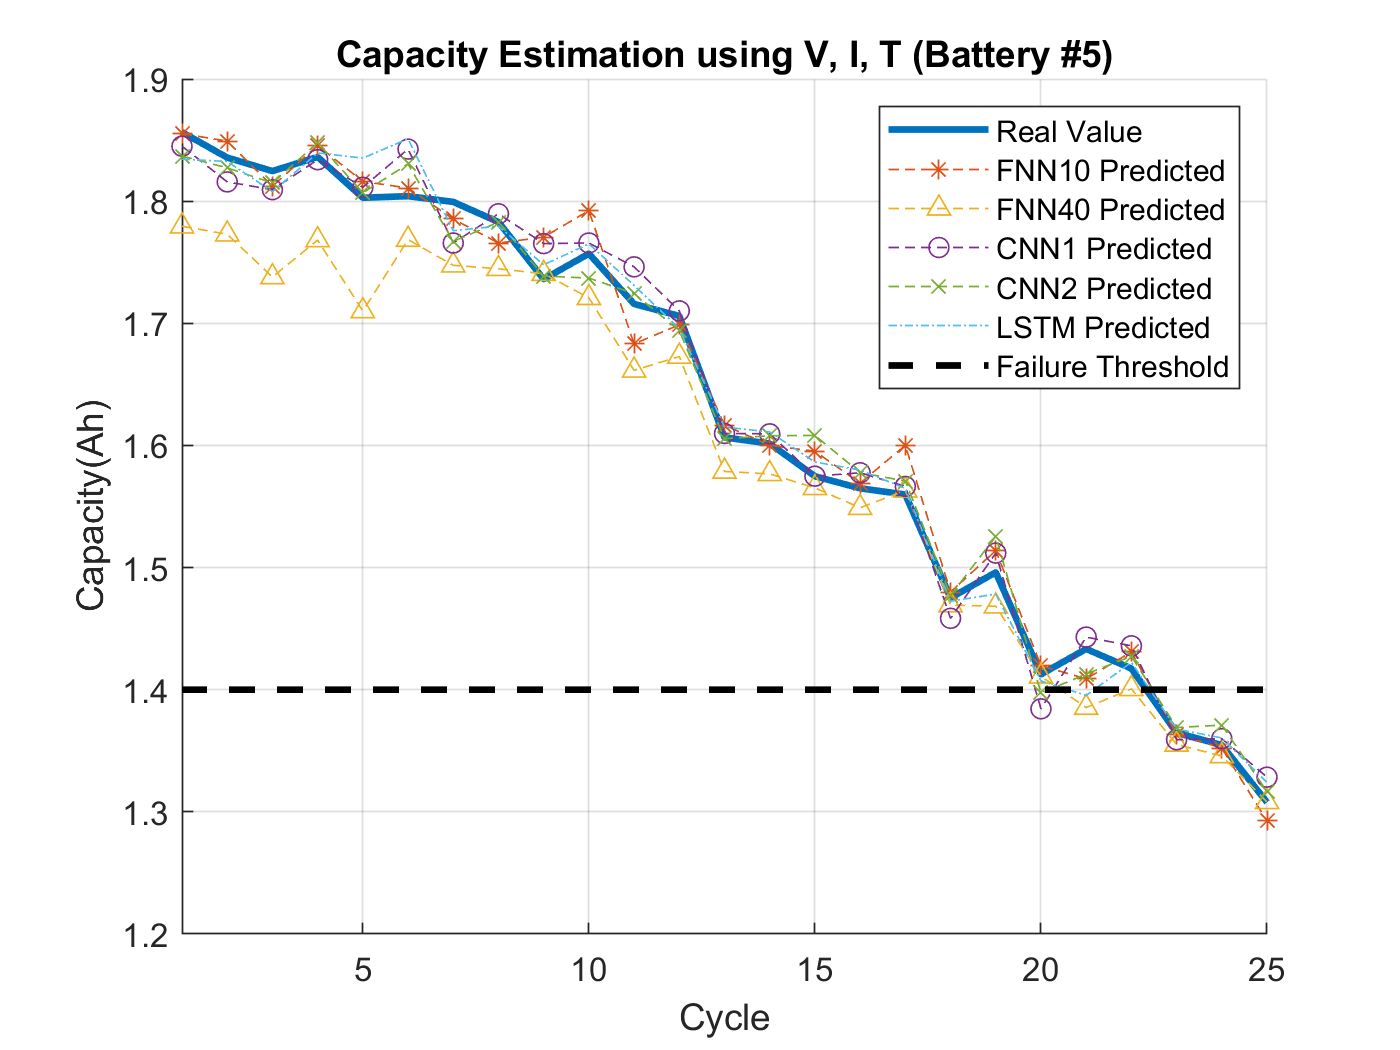

figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN10, '*--'), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.')
plot(1:25, 1.4*ones(1, 25),'k--','LineWidth', 2), xlim([1 25])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN10 Predicted', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted', 'Failure Threshold')

RMSE

rmse_pFNN10 = sqrt(mean(( Train_Output' - pFNN10 ).^2))

rmse_pFNN10 = 0.0182

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))

rmse_pFNN40 = 0.0432

rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))

rmse_pCNN1 = single
0.0178

rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))

rmse_pCNN2 = single
0.0161

rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))

rmse_pLSTM = single
0.0177